%DEMO_ART Demonstrates the use of, and results from, the ART methods
%
% This script illustrates the use of the ART methods Kaczmarz, symmetric
% Kaczmarz, and randomized Kaczmarz.
%
% The script creates a parallel-beam CT test problem and solves it with the
% ART methods.  The exact image and the results from the methods are shown.
%
% See also: demo_cart, demo_constraints, demo_custom_all, demo_matrixfree,
% demo_relaxpar, demo_sirt, demo_stoprules, demo_training.

% Code written by: Per Christian Hansen, Jakob Sauer Jorgensen, and 
% Maria Saxild-Hansen, 2010-2017.

% This file is part of the AIR Tools II package and is distributed under
% the 3-Clause BSD License. A separate license file should be provided as
% part of the package. 
% 
% Copyright 2017 Per Christian Hansen, Technical University of Denmark and
% Jakob Sauer Jorgensen, University of Manchester.

clear, clc
fprintf(1,'Starting demo_art:\n\n');

Starting demo_art:




% Set the parameters for the test problem.
N = 50;           % The image is N-times-N..
theta = 0:2:178;  % No. of used angles.
p = 75;           % No. of parallel rays.

fprintf(1,'Creating a parallel-beam tomography test problem\n');

Creating a parallel-beam tomography test problem


fprintf(1,'with N = %2.0f, theta = %1.0f:%1.0f:%3.0f, and p = %2.0f.',...
    [N,theta(1),theta(2)-theta(1),theta(end),p]);

with N = 50, theta = 0:2:178, and p = 75.

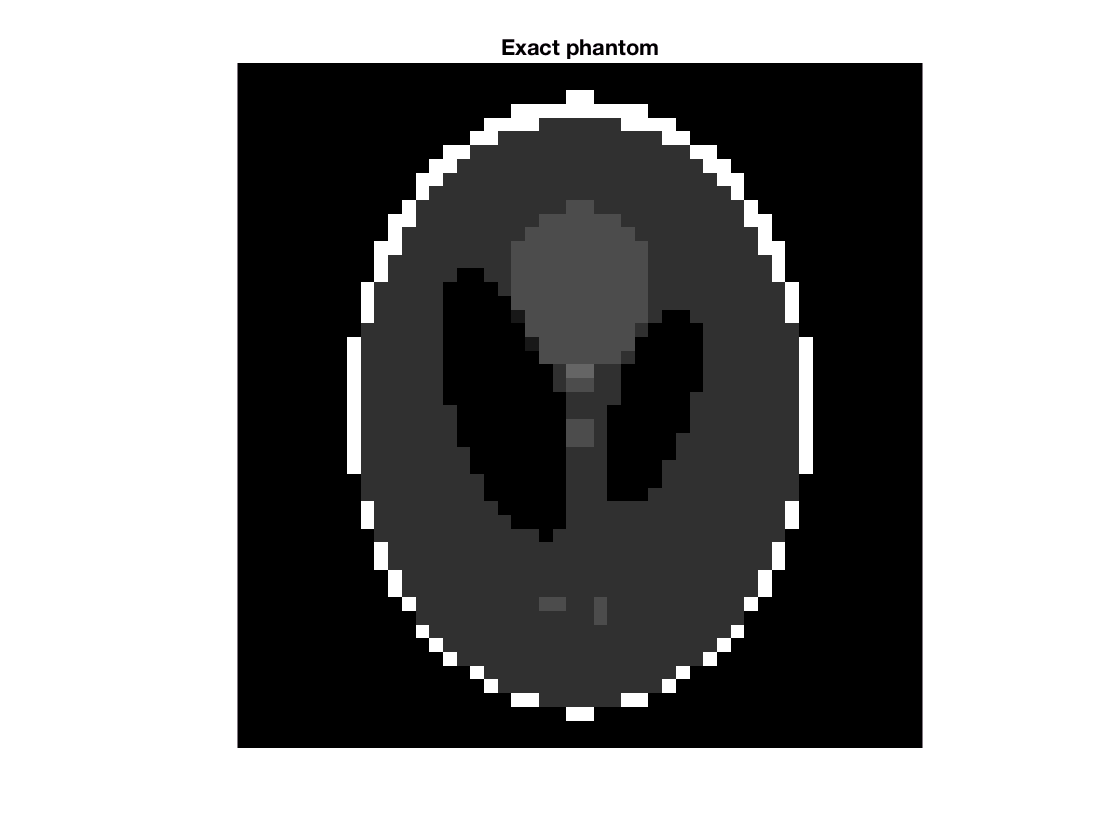


% Create the test problem.
[A,b,x] = paralleltomo(N,theta,p);

% Show the exact solution.
figure(1), clf
subplot()
% subplot(2,2,1)
imagesc(reshape(x,N,N)), colormap gray, axis image off
c = caxis;
title('Exact phantom')

fprintf(1,'\n\n');


x0 = zeros(N ^ 2, 1);
plotter = Plotter(x, N, c, true);

## Iteration settings

k = 30;           % Number of iterations.
run = @(type) art(type,A,b,k,x0,struct('verbose', 10,'waitbar',true));

## Perform the Kaczmarz iterations.

type = 'kaczmarz';
[Xrand, info] = run(type);

 1/30:  resnorm=1.08e+02  relaxpar=1.00e+00  time(iter/total)=8.30e-01/2.25e+00 secs.
11/30:  resnorm=2.79e+01  relaxpar=1.00e+00  time(iter/total)=7.72e-01/8.43e+00 secs.
21/30:  resnorm=1.21e+01  relaxpar=1.00e+00  time(iter/total)=7.21e-01/1.51e+01 secs.
30/30:  resnorm=6.27e+00  relaxpar=1.00e+00  time(iter/total)=9.79e-01/1.99e+01 secs.


 
For information about MathWorks, go to:
http://www.mathworks.com/company/aboutus/contact_us
or call +1 508 647 7000.
 
Relative error = 3.740 %


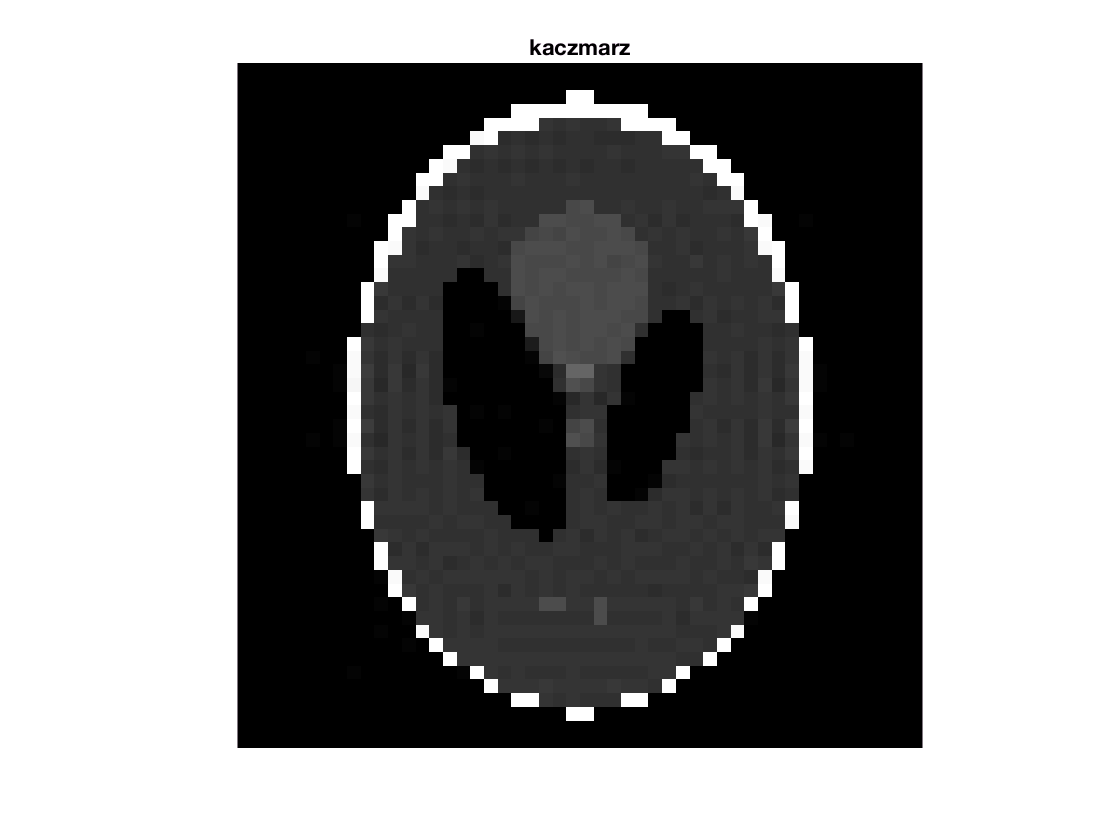

plotter.plot(Xrand, type);

## Perform the randomized Kaczmarz iterations.

type = 'randkaczmarz';
[Xrand, info] = run(type);

 1/30:  resnorm=2.60e+01  relaxpar=1.00e+00  time(iter/total)=1.33e+00/5.63e+00 secs.
11/30:  resnorm=2.05e+00  relaxpar=1.00e+00  time(iter/total)=3.47e-01/1.18e+01 secs.
21/30:  resnorm=1.06e+00  relaxpar=1.00e+00  time(iter/total)=3.87e-01/1.74e+01 secs.
30/30:  resnorm=7.10e-01  relaxpar=1.00e+00  time(iter/total)=6.21e-01/2.16e+01 secs.


 
For information about MathWorks, go to:
http://www.mathworks.com/company/aboutus/contact_us
or call +1 508 647 7000.
 
Relative error = 4.188 %


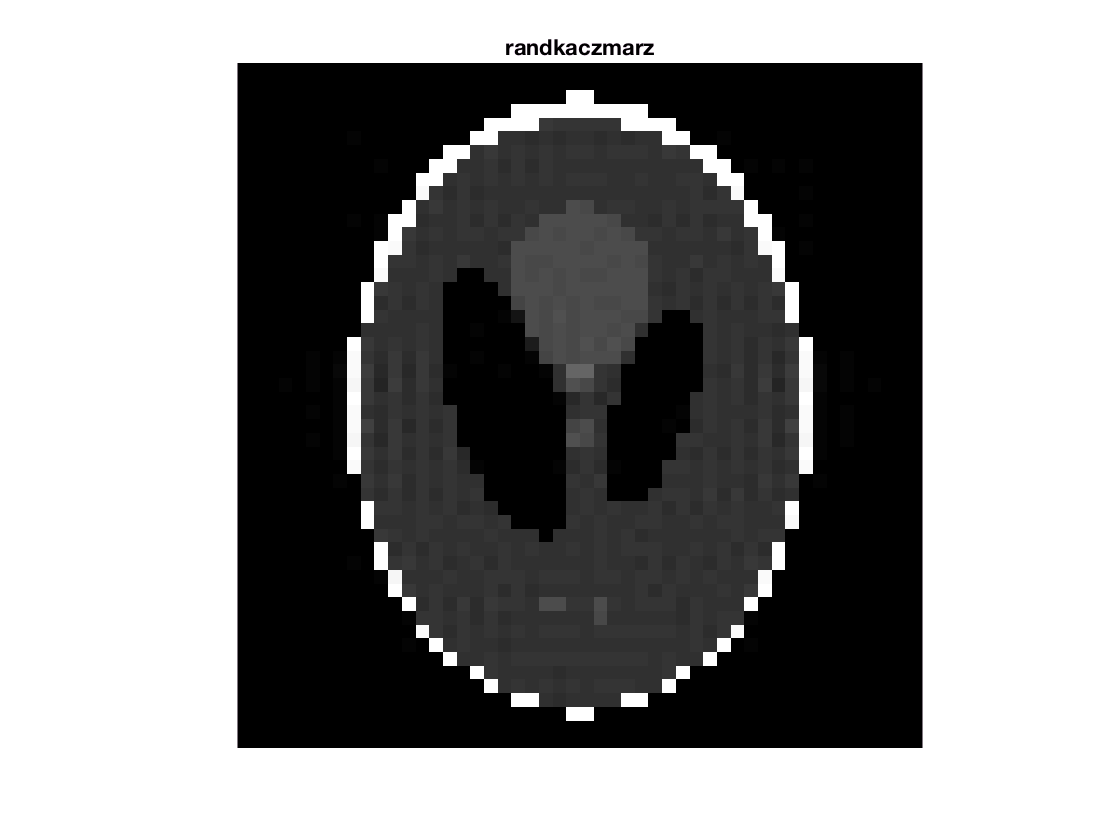

plotter.plot(Xrand, type);

## SK

type = 'SK';
[Xrand, info] = run(type);

 1/30:  resnorm=6.71e+01  relaxpar=1.00e+00  time(iter/total)=1.19e+00/2.74e+00 secs.
11/30:  resnorm=1.21e+00  relaxpar=1.00e+00  time(iter/total)=1.43e+00/1.12e+01 secs.
21/30:  resnorm=4.03e-01  relaxpar=1.00e+00  time(iter/total)=1.52e+00/2.12e+01 secs.
30/30:  resnorm=2.18e-01  relaxpar=1.00e+00  time(iter/total)=8.65e-01/3.16e+01 secs.


 
For information about MathWorks, go to:
http://www.mathworks.com/company/aboutus/contact_us
or call +1 508 647 7000.
 
Relative error = 1.120 %


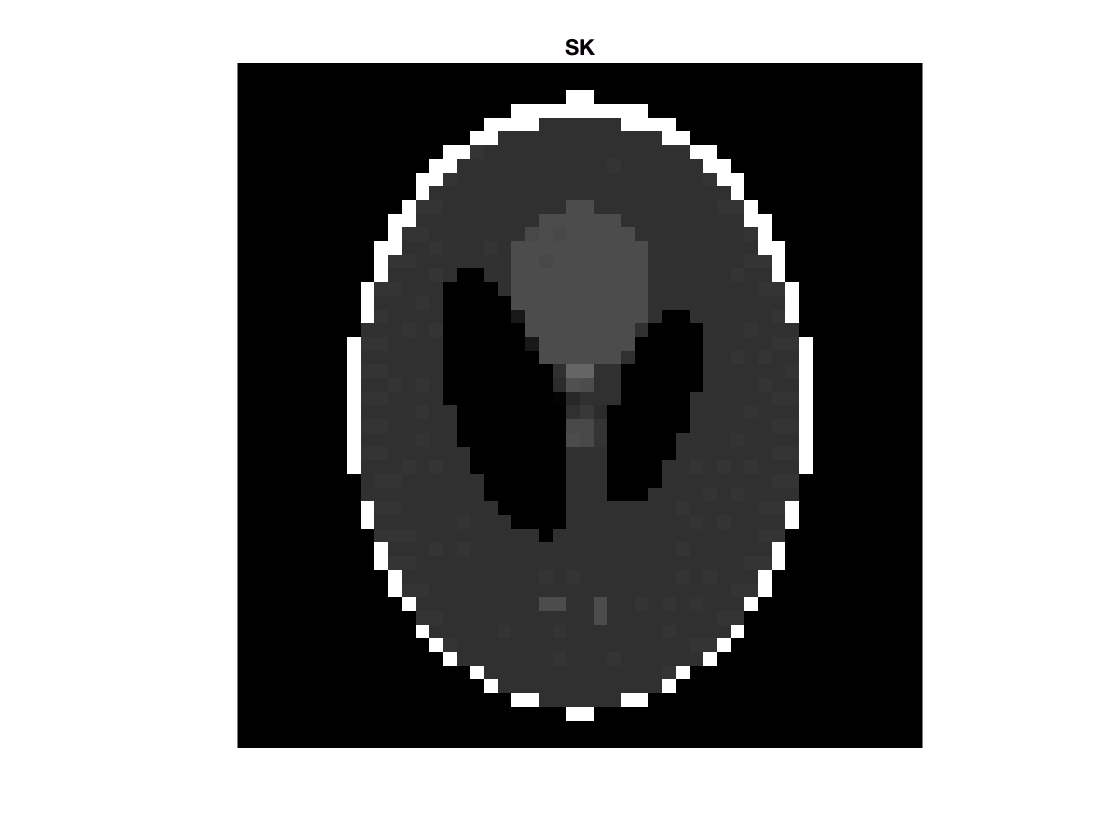

plotter.plot(Xrand, type);

## RSK

type = 'RSK';
[Xrand, info] = run(type);

1/3:  resnorm=2.07e+01  relaxpar=1.00e+00  time(iter/total)=8.68e-01/1.70e+00 secs.
3/3:  resnorm=4.43e+00  relaxpar=1.00e+00  time(iter/total)=8.16e-01/3.41e+00 secs.


 
For information about MathWorks, go to:
http://www.mathworks.com/company/aboutus/contact_us
or call +1 508 647 7000.
 
Relative error = 9.646 %
sparsity = 628
sparsity_acc = 42.375 %


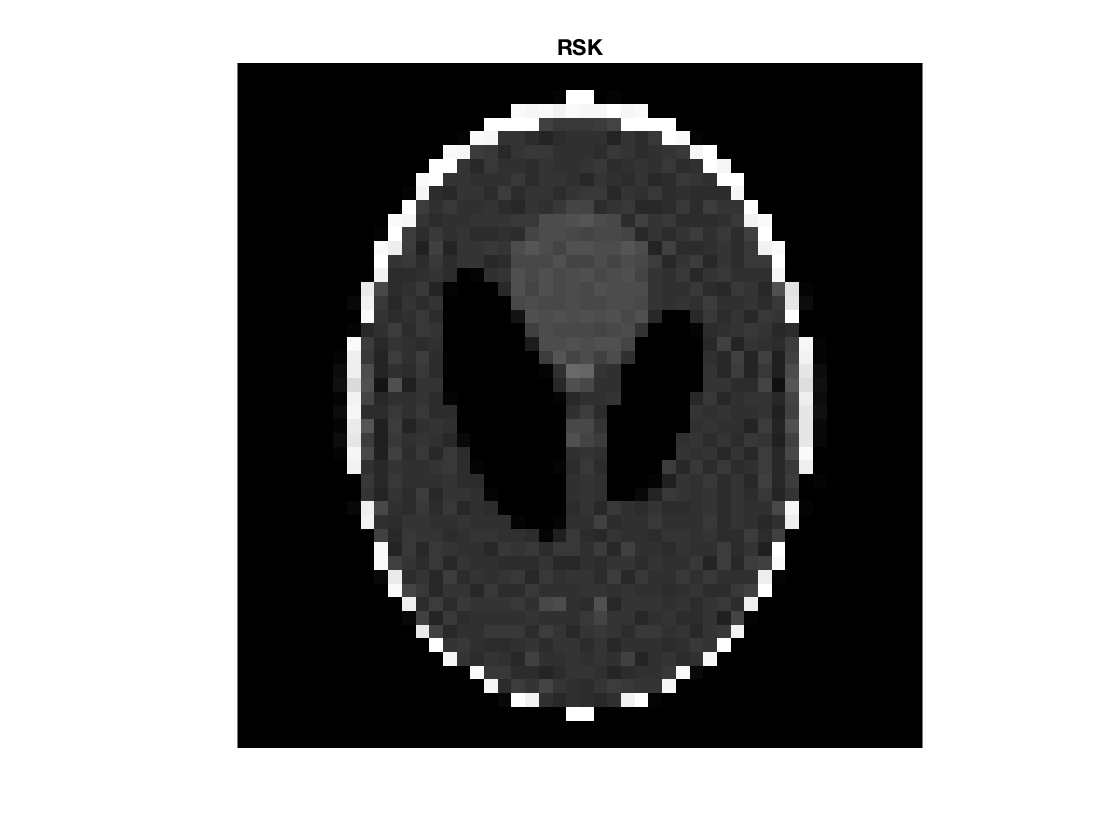

plotter.plot(Xrand, type)